Response of linear time-invariant (LTI) systems to arbitrary input signal in time and 

frequency domains.

m = 0:1:15;
x = (0.8).^m

x =     1.0000    0.8000    0.6400    0.5120    0.4096    0.3277    0.2621    0.2097    0.1678    0.1342    0.1074    0.0859    0.0687    0.0550    0.0440    0.0352


n = 0:1:10;
h = (1.1).^n

h =     1.0000    1.1000    1.2100    1.3310    1.4641    1.6105    1.7716    1.9487    2.1436    2.3579    2.5937


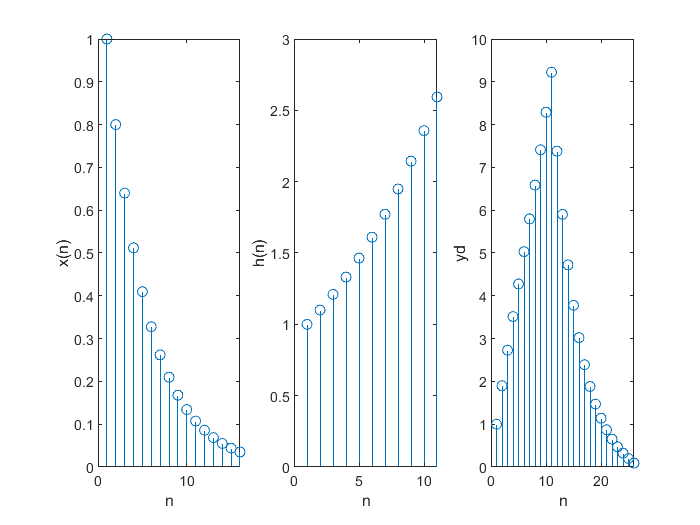

yd = conv(x,h);
figure;
subplot(1,3,1)
stem(x)
xlabel('n')
ylabel('x(n)')
subplot(1,3,2)
stem(h)
xlabel('n')
ylabel('h(n)')
subplot(1,3,3)
stem(yd)
xlabel('n')
ylabel('yd')

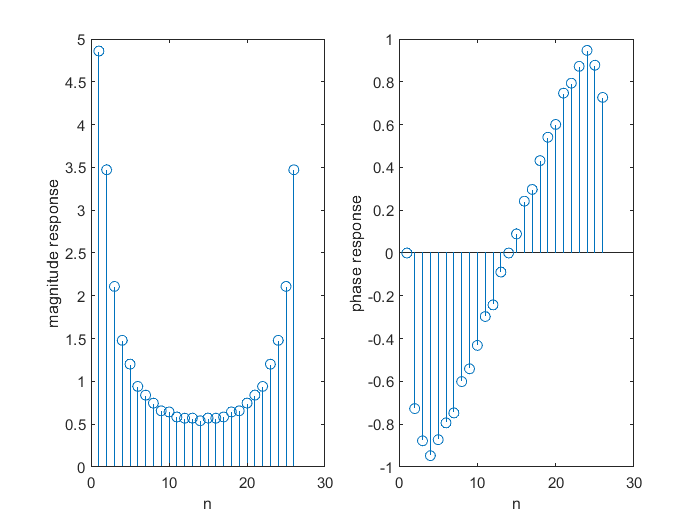

Lx = length(x);
Lh = length(h);
L = Lx +Lh-1;
X = fft(x, L); 
H = fft(h, L); 
mX = abs(X); 
pX = angle(X); 
figure;
subplot(1,2,1)
stem(mX)
xlabel('n')
ylabel('magnitude response')
subplot(1,2,2)
stem(pX)
xlabel('n')
ylabel('phase response')

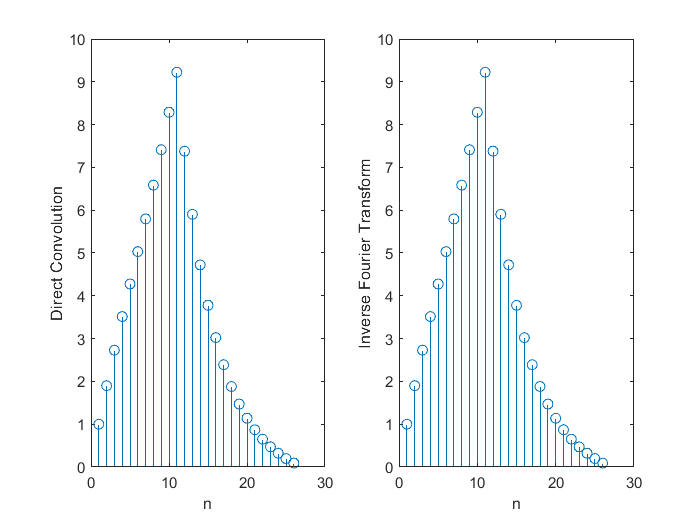

Y=X.*H;
yf=ifft(Y,L);
figure;
subplot(1,2,1)
stem(yd)
xlabel('n')
ylabel('Direct Convolution')
subplot(1,2,2)
stem(yf)
xlabel('n')
ylabel('Inverse Fourier Transform')